# ACM 11: Week 5 In-class exercise 2

## Newton's method (second-order)

In this exercise we will explore how the Newton's method behaves differently when we change the step sizes. Again, let's consider the same unconstrained optimization problem:


$$\min_{(x,y) \in \mathbb{R}^{2}}\frac{1}{2}(10x^2+y^2)+5\log(1+e^{-x-y})$$


The code block below sets up the objective function, its gradient, and its associated Hessian matrix:

% Set up the optimization problem
% Grid for plots
[x,y] = meshgrid(linspace(-20,20),linspace(-5,20));
% Objective function 
f = @(x,y) 1/200*((10*x.^2+y.^2)/2+5*log(1+exp(-x-y))); 
% Gradient function
df = @(x,y) 1/200*[10*x-5*exp(-x-y)./(1+exp(-x-y)) ; y-5*exp(-x-y)./(1+exp(-x-y)) ]; 
% Hessian function
hessf = @(x,y) [exp(- x - y)./(40*(exp(- x - y) + 1)) - exp(- 2*x - 2*y)./(40*(exp(- x - y) + 1)^2)+ 1/20,...
                exp(- x - y)./(40*(exp(- x - y) + 1)) - exp(- 2*x - 2*y)./(40*(exp(- x - y) + 1)^2);
                exp(- x - y)./(40*(exp(- x - y) + 1)) - exp(- 2*x - 2*y)./(40*(exp(- x - y) + 1)^2),...
                exp(- x - y)./(40*(exp(- x - y) + 1)) - exp(- 2*x - 2*y)./(40*(exp(- x - y) + 1)^2) + 1/200];

**(0) Please include all the names of your group members here:**

**Kyle McGraw**

**(1) Let's first try using the Newton's method without a line search. Change the fixed step size **$$\alpha$$** using the drop-down menu and observe how Newton's method behaves differently. Run the code for each value of **$$\alpha$$ **provided**, **and for each step size, report whether Newton's method converges. If it does converge, how many iterations does it require?**

**For 1, it converges in 4 iterations. For 0.5, it converges in 20 iterations. For 1.5, it does not coverge.**

% Contour plot
figure(1); clf;
[c,h] = contour(x,y,f(x,y),[1e-3, 1e-2, 5e-2, 0.1 0.2 0.5 1.5 1 2 3 4 5 6 7 8 9 10]); % contour plot
clabel(c,h)
grid on; hold on

% Set the parameters
xn = 20; % initial x guess
yn = 20; % initial y guess
Nmax = 500; % maximum iterations

% Label the "exact" solution
a = 0.112467185172334; 
b = 1.124671851723441 ; 
plot(a,b,'rx','MarkerSize',15); 

The code block below performs Newton's method without line search:

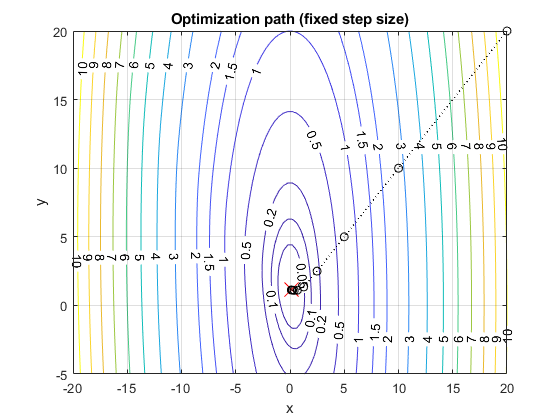

iterates_1 = zeros(Nmax,2); % initialize array for storing error
alpha = 0.5; % varying step size
for i = 1:Nmax
    g = df(xn,yn);% evaluate gradient
    hessf_eval = hessf(xn,yn); % evaluate hessian matrix
    g = hessf_eval\g; % apply inverse hessian to gradient, get newton direction

    figure(1);
    % Plot the optimization path
    plot([xn, xn-alpha*g(1)],[yn yn-alpha*g(2);],'k:','LineWidth',1);
    hold on
    plot(xn,yn,'ko')
    xn = xn - alpha*g(1); % go down the newton direction in x direction
    yn = yn - alpha*g(2);
    iterates_1(i,:) = [xn yn];

    % convergence check
    if norm(df(xn,yn)) < 1e-6
        break
    end
end
iterates_1 = iterates_1(1:i,:);

xlabel('x')
ylabel('y')
title('Optimization path (fixed step size)')

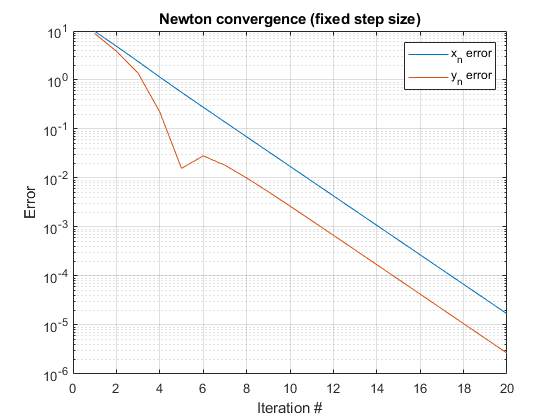


% Plot the decay of the error's absolute value in two directions
a = 0.112467185172334; b = 1.124671851723441 ; 
figure(2); clf; 
semilogy(abs(iterates_1(:,1)-a)); hold on 
semilogy(abs(iterates_1(:,2)-b)); grid on
xlabel('Iteration #')
ylabel('Error')
legend('x_n error','y_n error')
title('Newton convergence (fixed step size)')
set(gca,'fontsize',10);

**(2) Now let's try using Newton's method with a line search (Note that the helper function "bisection.m" is provided). Run the provided code. How many iterations does Newton's method take to converge when we do a line search? What is the price we pay for this faster convergence?**

**It only takes 2 iterations now, but each iteration is more computationally expensive.**

% Contour plot
figure(3); clf;
[c,h] = contour(x,y,f(x,y),[1e-3, 1e-2, 5e-2, 0.1 0.2 0.5 1.5 1 2 3 4 5 6 7 8 9 10]); %contour plot
clabel(c,h)
grid on; hold on

% Set the parameters
xn = 20; % initial x guess
yn = 20; % initial y guess
Nmax = 500; % maximum iterations

% Label the "exact" solution
a = 0.112467185172334; 
b = 1.124671851723441 ; 
plot(a,b,'rx','MarkerSize',15); 

The code block below performs Newton's method with line search, where the bisection method is used to find the optimal step size in each iteration:

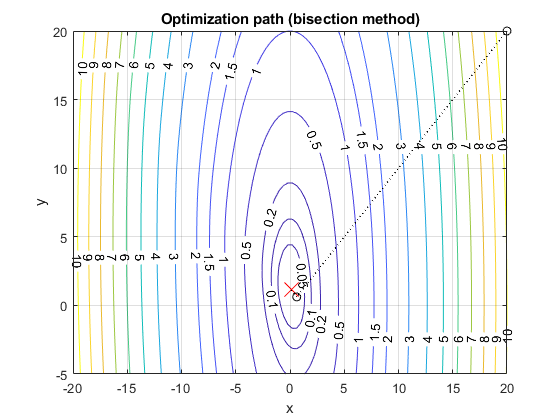

iterates_2= zeros(Nmax,2); % initialize array for storing error
for j = 1:Nmax
    g = df(xn,yn);% evaluate gradient
    hessf_eval = hessf(xn,yn); % evaluate hessian matrix
    g = hessf_eval\g; % apply inverse hessian to gradient, get newton direction
    
    g = g/norm(g);
    dfv = @(x) (hessf(x(1),x(2))\df(x(1),x(2)))'*g; 
    an = bisection(dfv,[xn; yn],[xn-40*g(1); yn-40*g(2)],1e-7,20);
    figure(3);
    % Plot the optimization path
    plot([xn, an(1,end)],[yn an(2,end)],'k:','LineWidth',1);
    hold on
    plot(xn,yn,'ko')
    xn = an(1,end);
    yn = an(2,end);
    iterates_2(j,:) = [xn yn];

    % convergence check
    if norm(df(xn,yn)) < 1e-6
        break
    end
end
iterates_2 = iterates_2(1:j,:);

xlabel('x')
ylabel('y')
title('Optimization path (bisection method)')

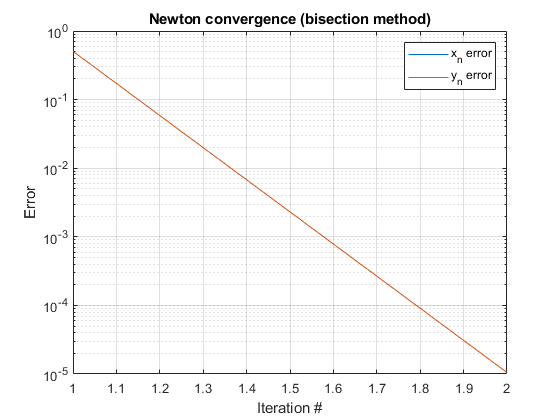


% Plot the decay of the error's absolute value in two directions
a = 0.112467185172334; b = 1.124671851723441 ; 
figure(4); clf; 
semilogy(abs(iterates_2(:,1)-a)); hold on 
semilogy(abs(iterates_2(:,2)-b)); grid on
xlabel('Iteration #')
ylabel('Error')
legend('x_n error','y_n error')
title('Newton convergence (bisection method)')
set(gca,'fontsize', 10);

**(3) How do your Newton results from this exercise compare with your Steepest Descent results from the previous exercise? Which converges in fewer iterations? Which has more expensive iterations?**

**This coverges in fewer iterations, but has more expensive iterations.**